# EDOs de primer orden

#### Ejemplo 4

% Definición de la función simbólica y(t)
syms y(t)

% Solución general de la EDO
y = dsolve(diff(y) == t * sin(t))

$$y = C_{1}+\sin\left(t\right)-t\,\cos\left(t\right)$$

#### Ejemplo 5

% Definición de la función simbólica y(t)
syms y(t)

% Solución general de la EDO
y = dsolve(diff(y) == y - t)

$$y = t+C_{1}\,{\mathrm{e}}^{t}+1$$


% Otra alternativa
%syms y(t)
%eqn = diff(y) == y - t;
%dsolve(eqn)

% También se puede definir la ecuación previamente. Esto es especialmente
% útil para ecuaciones diferenciales de órdenes superiores.
%syms y(t)
%Dy = diff(y)        % Definición como Dy de la derivada de y 
%eqn = Dy == y - t;  % Definimos la ecuación
%dsolve(eqn) 

#### Ejemplo 6

% Definición de la función simbólica y(t)
syms y(t)

% Definición de la primera derivada 
Dy = diff(y);

% Definición de la ecuación diferencial
eqn = Dy == y - t;

% Definición de la condición
cond = y(0) == 0;   
y = dsolve(eqn, cond)

$$y = t-{\mathrm{e}}^{t}+1$$

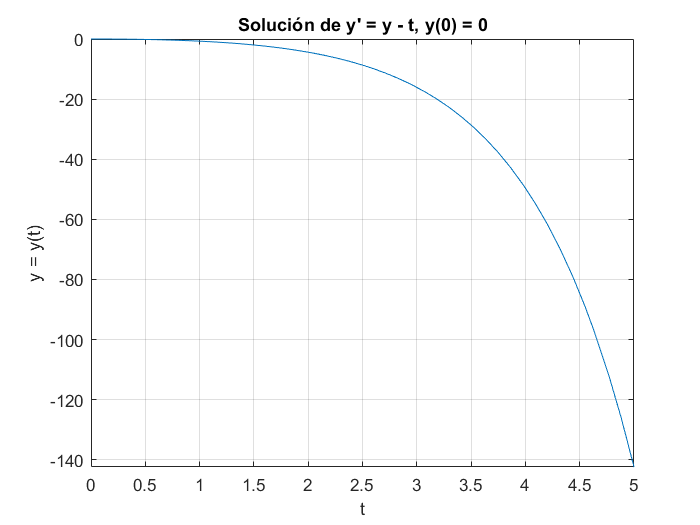


% Representación de la función y entre 0 y 5. Activación de cuadrícula
fplot(y, [0, 5]), grid
xlabel('t'), ylabel('y = y(t)'), title("Solución de y' = y - t, y(0) = 0")


% Evaluamos la función en t = 3.4
t = 3.4;
valor_solucion = eval(y)

valor_solucion = -25.5641

# EDOs de segundo orden (generalizable a otros órdenes)

#### Ejemplo 7 - Problema de condiciones iniciales (solución única)

% Definición de la función simbólica y(t)
syms y(t)

% Definición de la primera y segunda derivada 
Dy = diff(y);
D2y = diff(y, 2);

% EDO de segundo orden
eqn = D2y - 2 * Dy + y == (2 * t - 1) * exp(-t);

% Condiciones iniciales en froma de vector
cond = [y(0) == 0, Dy(0) == 5 / 8];

% Solución particular
y = dsolve(eqn, cond)

$$y = \frac{{\mathrm{e}}^{-t}\,\left(4\,t-2\,{\mathrm{e}}^{2\,t}+5\,t\,{\mathrm{e}}^{2\,t}+2\right)}{8}$$

#### Ejemplo 8 - Problema de condiciones iniciales (infinitas soluciones)

% Definición de la función simbólica y(t)
syms y(t)

% Definición de la segunda derivada 
D2y = diff(y, 2);

% EDO de segundo orden
eqn = D2y + 16 * y == 0;

% Condiciones iniciales en froma de vector
cond = [y(0) == 0, y(pi / 2) == 0];

% Solución
y = dsolve(eqn, cond)

$$y = -C_{1}\,\sin\left(4\,t\right)$$

# Sistemas de Ecuaciones Diferenciales

#### Ejemplo 9 - Sistema autónomo 

% Definición de las funciones simbólicas x e y.
syms x(t) y(t)

% Definición de las dos ecuaciones diferenciales
eqns = [diff(x) == x + 4 * y + 2, diff(y) == 2 * x - y];

% Solución general del sistema
sol = dsolve(eqns);
solx(t) = sol.x

$$solx(t) = 2\,{\mathrm{e}}^{3\,t}\,\left(C_{2}-\frac{2\,{\mathrm{e}}^{-3\,t}}{9}\right)-{\mathrm{e}}^{-3\,t}\,\left(C_{1}-\frac{2\,{\mathrm{e}}^{3\,t}}{9}\right)$$

soly(t) = sol.y 

$$soly(t) = {\mathrm{e}}^{-3\,t}\,\left(C_{1}-\frac{2\,{\mathrm{e}}^{3\,t}}{9}\right)+{\mathrm{e}}^{3\,t}\,\left(C_{2}-\frac{2\,{\mathrm{e}}^{-3\,t}}{9}\right)$$

#### Ejemplo 10

% Definición de las funciones simbólicas x e y.
syms x(t) y(t)

% Definición de las dos ecuaciones diferenciales
eqns = [diff(x) == x + 4 * y + 2, diff(y) == 2 * x - y];

% Condiciones iniciales en froma de vector 
conds = [x(0) == 0, y(0) == 0];

% Solución particular del sistema
sol = dsolve(eqns, conds);
solx(t) = sol.x

$$solx(t) = {\mathrm{e}}^{-3\,t}\,\left(\frac{2\,{\mathrm{e}}^{3\,t}}{9}-\frac{2}{9}\right)-2\,{\mathrm{e}}^{3\,t}\,\left(\frac{2\,{\mathrm{e}}^{-3\,t}}{9}-\frac{2}{9}\right)$$

soly(t) = sol.y

$$soly(t) = -{\mathrm{e}}^{-3\,t}\,\left(\frac{2\,{\mathrm{e}}^{3\,t}}{9}-\frac{2}{9}\right)-{\mathrm{e}}^{3\,t}\,\left(\frac{2\,{\mathrm{e}}^{-3\,t}}{9}-\frac{2}{9}\right)$$

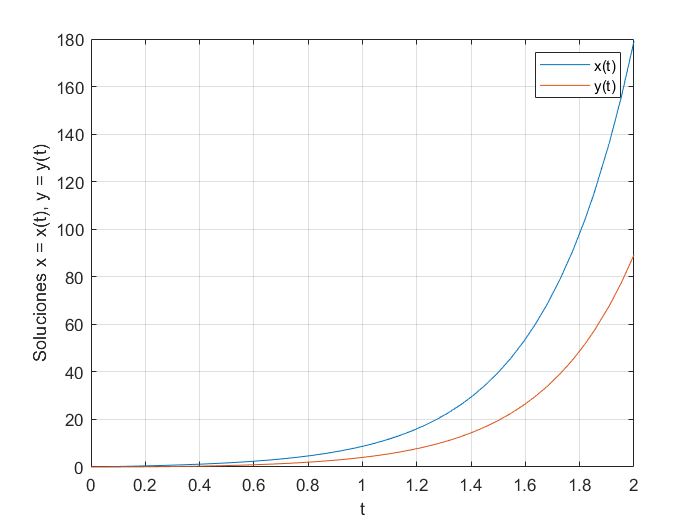


% Representación de las funciones x e y n el intervalo t en [0, 2]
fplot(solx(t), [0, 2]), hold on
fplot(soly(t), [0, 2]), grid
xlabel('t'), ylabel('Soluciones x = x(t), y = y(t)')
legend('x(t)', 'y(t)')

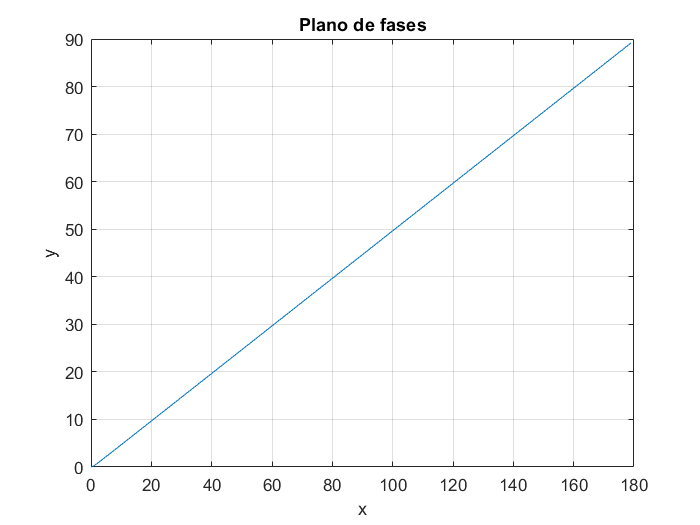


% Representación en el plano de fases
% Se consideran 100 puntos equiespaciados de [0, 2]
t = linspace(0, 2, 100);
x = eval(solx(t));
y = eval(soly(t));
figure, plot(x, y), grid 
xlabel('x'), ylabel('y')
title('Plano de fases') 